## **1. Linear SVM **

### **1.1 Iris flower classification with hard margin classifier**

In this case study, we classify the iris flowers by using hard margin SVM. We use the following 2 features and 2 species (labels), such that the dataset is linearly separable:

- **Features**: (sepal length, sepal width)

- **Labels**: (setosa, versicolor) 

#### **1) Load and split the dataset**

% Load the iris dataset
load fisheriris
% Extract two features and two species
X_train = meas(1:80, 1:2); y_train = species(1:80); % The first 80 samples are training set
X_test = meas(81:100, 1:2); y_test = species(81:100); % The subsequent 20 samples are test set

**2) Train a hard margin SVM classifier**

To train a hard margin SVM, set 'BoxConstraint' parameter to Inf.

% Train an SVM classifier
svm = fitcsvm(X_train, y_train, 'KernelFunction', 'linear', 'BoxConstraint', Inf);
sv = svm.SupportVectors; % Get the support vectors
beta = svm.Beta; % Get the coefficients of the linear classifier
b = svm.Bias; % Get the bias term of the linear classifier

**3) Prediction and the prediction accuracy**

% Predict
y_pred = predict(svm, X_test);

% Count the number of correct classified samples.
num_correct = 0;
for i = 1: length(y_test)
    num_correct = num_correct + strcmp(y_pred(i), y_test(i));
end
% Calculate the prediction accuracy
accuracy = num_correct/length(y_test)*100;
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 100


**4) Plot the results**

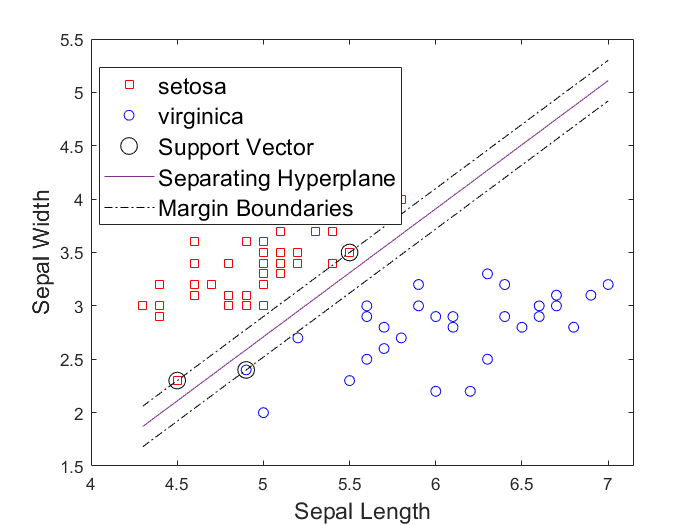

figure;
gscatter(X_train(:,1), X_train(:,2), y_train, 'rb', 'so'); hold on; % Plot the dataset
plot(sv(:,1), sv(:,2), 'ko', 'MarkerSize', 10); hold on; % Plot the support vectors

% The classifier
X1 = linspace(min(X_train(:,1)),max(X_train(:,1)),100);
X2 = -(beta(1)/beta(2)*X1)-b/beta(2);  
plot(X1,X2,'-'); hold on; % Plot the classifier

% The two margin boundaries
bnd1 = -(beta(1)/beta(2)*X1)-b/beta(2) + 1/beta(2);
bnd2 = -(beta(1)/beta(2)*X1)-b/beta(2) - 1/beta(2);

% Plot the two margin boundaries
plot(X1,bnd1,'k-.'); hold on;
plot(X1,bnd2,'k-.'); hold on;

xlabel('Sepal Length', 'Fontsize', 14);
ylabel('Sepal Width', 'Fontsize', 14);
legend('setosa', 'virginica', 'Support Vector', 'Separating Hyperplane', 'Margin Boundaries', 'Fontsize', 14)
hold off;

### **1.2 Iris flower classification with soft margin classifier **

In this case study, we classify the iris flowers by using soft margin SVM. We use the same dataset as that in the last case study. To train a soft margin SVM, set 'BoxConstraint' parameter to a specific value.

- The parameter 'BoxConstraint' controls the size of the margin. The default value of 'BoxConstraint' is 1. 

- A smaller value of 'BoxConstraint' results in a wider margin but may lead to misclassification of some training data points, while a larger value may lead to overfitting of the model to the training data. 

We use a drop down control to set 'BoxConstraint' to different values.

#### **1) Load and split the dataset**

% Load the iris dataset
load fisheriris
% Extract two features and two species
X_train = meas(1:80, 1:2); y_train = species(1:80); % The first 80 samples are training set
X_test = meas(81:100, 1:2); y_test = species(81:100); % The subsequent 20 samples are test set

**2) Train a soft margin SVM classifier**

To train a hard margin SVM, set 'BoxConstraint' parameter to Inf.

BoxConstraint = 1;
% Train a soft margin SVM classifier
svm = fitcsvm(X_train, y_train, 'KernelFunction', 'linear', 'BoxConstraint', BoxConstraint);
sv = svm.SupportVectors; % Get the support vectors
beta = svm.Beta; % Get the coefficients of the linear classifier
b = svm.Bias; % Get the bias term of the linear classifier

**3) Prediction and the prediction accuracy**

% Predict
y_pred = predict(svm, X_test);

% Count the number of correct classified samples.
num_correct = 0;
for i = 1: length(y_test)
    num_correct = num_correct + strcmp(y_pred(i), y_test(i));
end
% Calculate the prediction accuracy
accuracy = num_correct/length(y_test)*100;
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 100


**4) Plot the results**

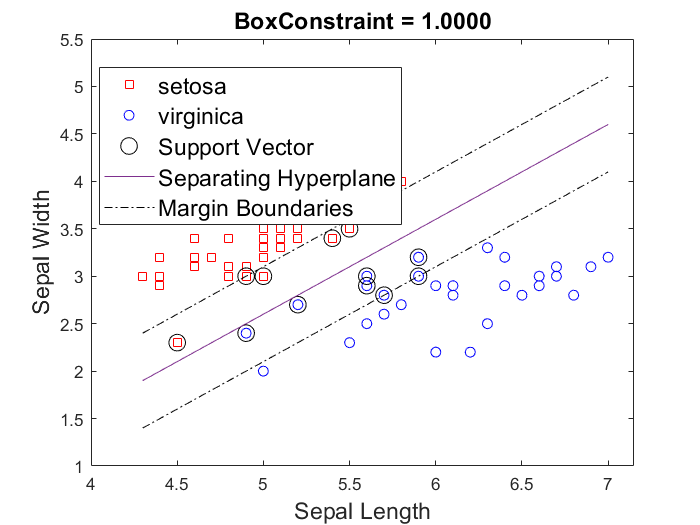

BoxConstraint = 100

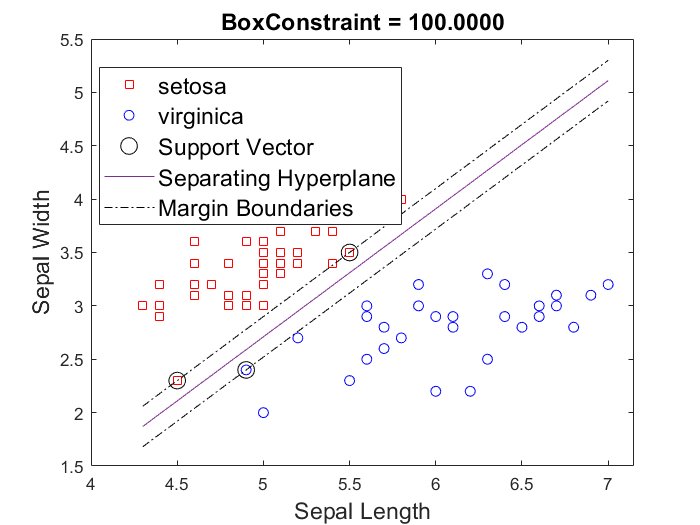

figure;
gscatter(X_train(:,1), X_train(:,2), y_train, 'rb', 'so'); hold on; % Plot the dataset
plot(sv(:,1), sv(:,2), 'ko', 'MarkerSize', 10); hold on; % Plot the support vectors

% The classifier
X1 = linspace(min(X_train(:,1)),max(X_train(:,1)),100);
X2 = -(beta(1)/beta(2)*X1)-b/beta(2);  
plot(X1,X2,'-'); hold on; % Plot the classifier

% The two margin boundaries
bnd1 = -(beta(1)/beta(2)*X1)-b/beta(2) + 1/beta(2);
bnd2 = -(beta(1)/beta(2)*X1)-b/beta(2) - 1/beta(2);

% Plot the two margin boundaries
plot(X1,bnd1,'k-.'); hold on;
plot(X1,bnd2,'k-.'); hold on;

xlabel('Sepal Length', 'Fontsize', 14);
ylabel('Sepal Width', 'Fontsize', 14);
title(sprintf('BoxConstraint = %.4f', BoxConstraint), 'Fontsize', 14);
legend('setosa', 'virginica', 'Support Vector', 'Separating Hyperplane', 'Margin Boundaries', 'Fontsize', 14)
hold off;

### 1.3. Linear SVM - banknote classification

In this case study, we train a linear SVM to detect counterfeit banknotes. We use data that are extracted from images that were taken from genuine and forged banknote-like specimens.�

**1) Load the dataset from a csv file**

**The first 4 columns are features, while the last column is the labels.**

- Features: (variance, skewness, curtosis, entropy) of Wavelet transformed image.�

- Labels: {0, 1}, where 0 and 1 represent forged and genuine banknotes respectively.

% load the banknote dataset
bankdata = readtable('banknote.csv');

ans = 960

ans = 320

Accuracy: 97.1875


    Actual    Predicted
    ______    _________

      0           0    
      1           0    
      1           0    
      1           0    
      1           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0    
      0           0

X = bankdata{:, 1:4};
y = bankdata{:, 'Class'};

**2) Split the dataset into training set and test set**

% Split into training and test data by the ratio 75% and 25%, respectively.
cvObj = cvpartition(size(X, 1), 'HoldOut', 0.75);
idx = cvObj.test;
X_train = X(idx,  :); X_test  = X(~idx, :); 
y_train = y(idx,  :); y_test  = y(~idx, :); 

**3) Training**

% Train a linear SVM
svclassifier = fitcsvm(X_train, y_train, 'KernelFunction', 'linear', 'Standardize', true);

**4) Prediction**

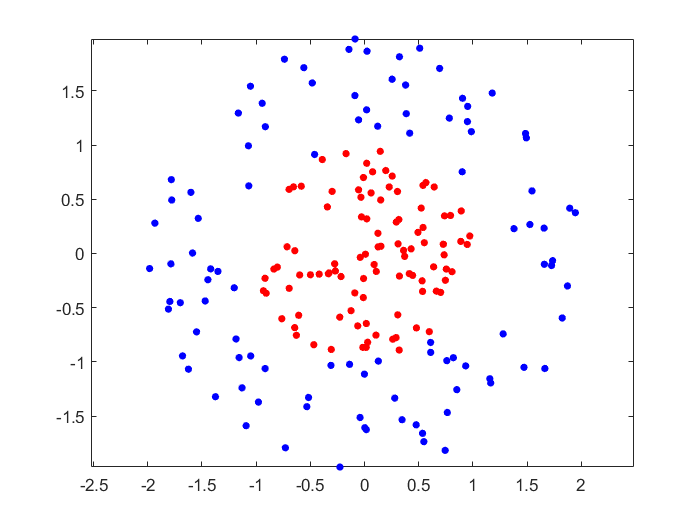

% Predict
y_pred = predict(svclassifier, X_test);
accuracy_score = sum(y_test == y_pred)/length(y_test)*100; % Prediction accuracy
disp(['Accuracy: ', num2str(accuracy_score)]);

df_preds = table(y_test, y_pred);
df_preds.Properties.VariableNames = {'Actual', 'Predicted'};

disp(df_preds);

## 2. Nonlinear SVM

### 2.1. Nonlinear SVM - 2D point classification

This is a simple example for illustrative purpose, in which we use a hand-crafted dataset.

**1) Create the dataset**

We generate the data by the following code.  We don’t need to understand the data generation code.

rng(1); % For reproducibility
r = sqrt(rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
r2 = sqrt(3*rand(100,1)+1); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points
figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
axis equal
hold off;

**2) Data split**

X = [data1;data2]; % Features of the dataset
% Labels of the dataset. The first 100 data are +1, the rest are -1.
y = ones(200,1); y(1:100) = -1;

Accuracy: 100



% Split into training and test data by the ratio 75% and 25%, respectively.
cvObj = cvpartition(size(X, 1), 'HoldOut', 0.75);
idx = cvObj.test;
X_train = X(idx,  :); X_test  = X(~idx, :); 
y_train = y(idx,  :); y_test  = y(~idx, :); 

**3) Training**

%Train a nonlinear SVM Classifier with 'rbf' kernel
svm = fitcsvm(X_train,y_train,'KernelFunction','rbf', 'BoxConstraint', 1);

**4) Prediction**

% Predict
y_pred = predict(svm, X_test);
accuracy_score = sum(y_test == y_pred)/length(y_test)*100; % Prediction accuracy
disp(['Accuracy: ', num2str(accuracy_score)]);

**5) Plot the results**

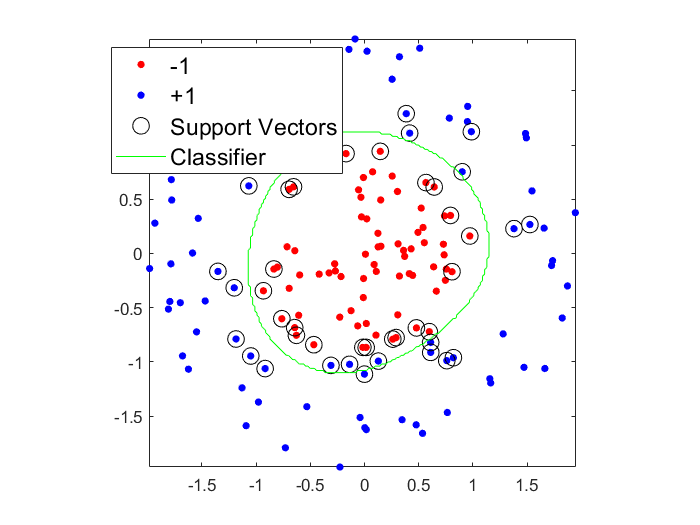

% Plot the data and the support vectors
figure;
gscatter(X_train(:,1),X_train(:,2),y_train,'rb','.'); hold on; % Plot the data
sv = svm.SupportVectors;

plot(sv(:,1), sv(:,2), 'ko', 'MarkerSize', 10); hold on; % Plot the support vectors

% Plot the classifier (optional)
d = 0.02;
[x1, x2] = meshgrid(min(X_train(:,1)):d:max(X_train(:,1)), min(X_train(:,2)):d:max(X_train(:,2)));
XGrid = [x1(:),x2(:)];
yGrid = predict(svm, XGrid);
contour(x1, x2, reshape(yGrid,size(x1)), [0 0], 'g'); hold on;
legend('-1','+1','Support Vectors', 'Classifier', 'Fontsize', 14);
axis equal; hold off;


### 2.2. Nonlinear SVM - raisin classification

Turkey is one of the countries that ranks top in the world’s grape, 37% are dried. Assessing and determining the quality of raisin are essential. However, human-made procedures from traditional methods are inconsistent and inefficient. Thus, we aim to develop a nonlinear SVM classifier to quickly and precisely classify different raisins.

**1) Load the dataset**

- **Features**: (Area, MajorAxisLength, MinorAxisLength, Eccentricity, ConvexArea, Extent, Perimeter)

- **Labels**: Class 1: Kecimen; Class 0: Besni

% Load data
data = readtable('raisin_dataset.csv');
X = data{:, 1:7};
y = data{:, 'Class'};

**2) Split the dataset**

% Split into training and test data by the ratio 75% and 25%, respectively.
cvObj = cvpartition(size(X, 1), 'HoldOut', 0.75);

Accuracy: 100


idx = cvObj.test;
X_train = X(idx,  :); X_test  = X(~idx, :);
y_train = y(idx,  :); y_test  = y(~idx, :);

**3) Train and predict**

% Train SVM model
SVMModel = fitcsvm(X_train, y_train, 'KernelFunction', 'gaussian', 'Standardize', true);
% Predict on test data
y_pred = predict(SVMModel, X_test);
accuracy_score = sum(y_test == y_pred)/length(y_test)*100;
disp(['Accuracy: ', num2str(accuracy_score)]);

### 2.3. Choose kernel by corss validation

In this case study, we use the raisin classification example to show how to choose kernel by using corss validation. The candidate kernels are 'polynomial', 'rbf', 'gaussian'. 

**1) Load and split the dataset**

% Load data
data = readtable('raisin_dataset.csv');
X = data{:, 1:7}; % Features
y = data{:, 'Class'}; % Labels

**2) Corss validation**

kernels = {'polynomial', 'rbf', 'gaussian'}; % Candidate kernels
accuracy_scores = zeros(1, length(kernels)); % Accuracy scores of the candidate kernels
k = 20; % k controls the number of corss validations.

Best kernel: rbf


for i = 1:k

Average accuracy: 0.87044


    % Split into training and test data by the ratio 75% and 25%, respectively.
    cvObj = cvpartition(size(X, 1), 'HoldOut', 0.75);
    idx = cvObj.test;
    X_train = X(idx,  :); X_test  = X(~idx, :);
    y_train = y(idx,  :); y_test  = y(~idx, :);

    for j = 1:length(kernels)
        % Train SVM model
        SVMModel = fitcsvm(X_train, y_train, 'KernelFunction', kernels{j}, 'Standardize', true);
        % Predict on test data
        y_pred = predict(SVMModel, X_test);
        %Calculate the accuracy scores of the j-th kernel
        accuracy = sum(y_test == y_pred)/length(y_test);
        accuracy_scores(j) = accuracy_scores(j) + accuracy;
    end
end

**3) Select the kernel that has the highest prediction accuracy**

accuracy_scores = accuracy_scores/k; % The average accuracy scores of individual kernels
[max_acc,max_index] = max(accuracy_scores); % The max accuracy and the best kernel
disp(['Best kernel: ', kernels{max_index}]);
disp(['Average accuracy: ', num2str(max_acc)]);